# Hidden Steam Header System + Time Constants

clear; clc;

## =============================

Simulation settings

## =============================

Tsim = 2000;      
dt   = 5;         
N    = Tsim/dt;

t = (0:N-1)' * dt;

## =============================

Parameters

## =============================

a1 = 0.02;        
a2 = 0.015;       

b1 = 1e-4;        
b2 = 8e-5;        

T1_in = 350;      
T2_in = 345;      

tau_H = 300;      
sigma_H = 200;    

## =============================

Calculate Time Constants

## =============================

tau_T1 = 1/a1;
tau_T2 = 1/a2;
tau_hidden = tau_H;

fprintf('\n=== System Time Constants ===\n');


=== System Time Constants ===


fprintf('Tau T1        = %.2f s\n', tau_T1);

Tau T1        = 50.00 s


fprintf('Tau T2        = %.2f s\n', tau_T2);

Tau T2        = 66.67 s


fprintf('Tau Hidden H  = %.2f s\n\n', tau_hidden);

Tau Hidden H  = 300.00 s



## =============================

Allocate variables

## =============================

T1 = zeros(N,1);
T2 = zeros(N,1);
H  = zeros(N,1);

## =============================

Initial conditions

## =============================

T1(1) = 350;
T2(1) = 345;
H(1)  = 2e5;

## =============================

Generate hidden steam dynamics

## =============================

for k = 1:N-1
    dH = -(1/tau_H)*H(k) + sigma_H*randn;
    H(k+1) = H(k) + dt*dH;
end

## =============================

Simulate reactors

## =============================

for k = 1:N-1
    dT1 = a1*(T1_in - T1(k)) + b1*H(k);
    dT2 = a2*(T2_in - T2(k)) + b2*H(k);
    
    T1(k+1) = T1(k) + dt*dT1;
    T2(k+1) = T2(k) + dt*dT2;
end

%% =============================
% Write CSV using export function
%% =============================

export_hidden_steam_csv('hidden_steam_data.csv', t, T1, T2, H);

Saved 400 rows to "hidden_steam_data.csv".


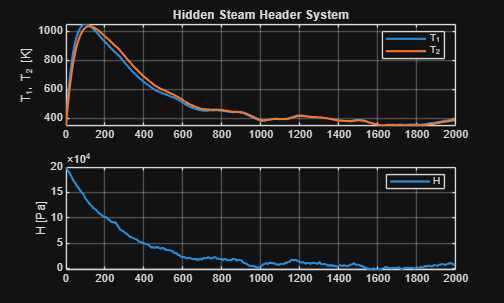

%% =============================
% Plot results
%% =============================

figure;

subplot(2,1,1);
plot(t, T1, 'LineWidth',1.6); hold on;
plot(t, T2, 'LineWidth',1.6);
grid on;
ylabel('T_1, T_2 [K]');
legend('T_1','T_2');
title('Hidden Steam Header System');

subplot(2,1,2);
plot(t, H, 'LineWidth',1.6);
grid on;
ylabel('H [Pa]');
legend('H');